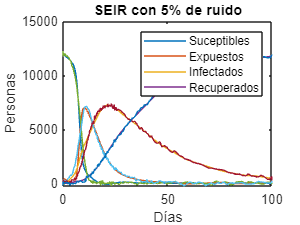

[t,y] = ode45(@vdp1,[0 100],[12000; 120; 15; 0]);


% Generar valores de ruido normalmente distribuidos
ruido = 100 * randn(size(y));

% Aplicar el ruido a las variables
y_ruidoso = y + ruido;

[max_y2, idx_y2] = max(y_ruidoso(:, 2));
[max_y3, idx_y3] = max(y_ruidoso(:, 3));

time_max_y2 = t(idx_y2);
time_max_y3 = t(idx_y3);


% Datos originales y_ruidoso
x = t';  % Valores de tiempo
y_data = y_ruidoso';  % Datos originales (trasponer para que coincidan las dimensiones)

% Crear una red neuronal feedforward
hiddenLayerSize = 10;  % Tamaño de la capa oculta
net = feedforwardnet(hiddenLayerSize);

% Dividir los datos en conjuntos de entrenamiento y prueba (opcional)
% Puedes ajustar esta parte según tus necesidades.
net.trainParam.epochs = 10;
net.divideFcn = 'dividerand';
net.divideParam.trainRatio = 0.7;
net.divideParam.valRatio = 0.15;
net.divideParam.testRatio = 0.15;

% Entrenar la red
net = train(net, x, y_data);

% Utilizar la red para predecir los datos suavizados
y_suavizado = net(x);

% Trazar las curvas suavizadas
figure;
plot(x, y_suavizado,'-');
hold on
plot(x,y_data)
title('SEIR con 5% de ruido');
xlabel('Días');
ylabel('Personas');
legend('Suceptibles','Expuestos','Infectados','Recuperados');

%legend('Suceptibles suavizados','Expuestos suavizados','Infectados suavizados','Recuperados suavizados');

%m=mean(1-abs(y_data(0,:)-y_suavizado(0,:)))
yy=y_data(1,:)

yy = 1.0e+04 *

    1.1787    1.1953    1.2001    1.1884    1.1896    1.1804    1.1945    1.1836    1.1937    1.1937    1.2100    1.2211    1.1966    1.2050    1.1880    1.1830    1.2042    1.1723    1.2041    1.2008    1.2042    1.1983    1.1793    1.1981    1.1804    1.1680    1.1809    1.1660    1.1554    1.1362    1.1295    1.0892    1.0723    1.0334    0.9932    0.9416    0.8756    0.7878    0.7056    0.6259    0.5300    0.4283    0.3361    0.2591    0.2082    0.1687    0.1477    0.1205    0.0895    0.0822


ys=y_suavizado(1,:)

ys = 1.0e+04 *

    1.1923    1.1923    1.1923    1.1923    1.1923    1.1923    1.1922    1.1922    1.1922    1.1922    1.1922    1.1921    1.1921    1.1919    1.1918    1.1916    1.1914    1.1906    1.1898    1.1890    1.1881    1.1840    1.1798    1.1756    1.1713    1.1650    1.1587    1.1522    1.1455    1.1369    1.1276    1.1170    1.1037    1.0838    1.0528    1.0012    0.9161    0.7959    0.6420    0.4807    0.3436    0.2518    0.1907    0.1514    0.1258    0.1152    0.1063    0.0988    0.0923    0.0864


m=mean(yy-ys)

m = 15.1942


save('yy.mat', 'yy');
save('ys.mat', 'ys');



function dydt = vdp1(t, y)
    B = 2.95;
    r = 0.04;
    o = 0.133111;
    N = 12135;
    dydt = [((-B) * y(1) * y(3)) / N; ((B * y(1) * y(3)) / N - (o * y(2))); o * y(2) - r * y(3); r * y(3)];
end